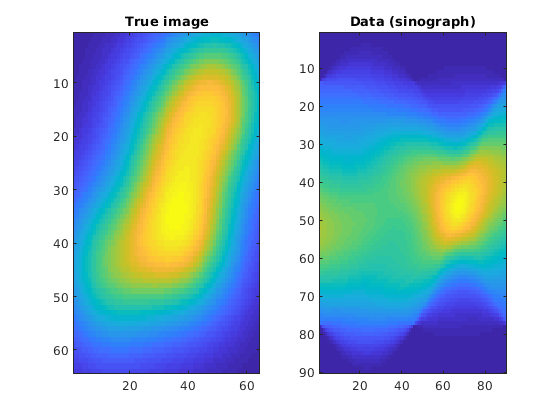

clc;
clear;
close all;
rng('default');

N = 64;          % Image is N-by-N pixels
theta = 0:2:178; % projection angles
p = 90;          % Number of rays for each angle

% Assemble the X-ray tomography matrix, the true data, and true image
K = paralleltomo(N, theta, p);

% Generate synthetic data
m_true = phantomgallery('smooth', N);
m_true = m_true(:);
d = K*m_true;

figure;
subplot(121);
imagesc(reshape(m_true, N, N));
title('True image');
subplot(122);
imagesc(reshape(d, p, length(theta)));
title('Data (sinograph)');

% Remove possibly 0 rows from K, and d
[K, d] = purge_rows(K, d);

% Rescale K, and d so that the l2 norm of each row is 1
s = sqrt(sum(K.*K, 2));
K = spdiags(1./s,0)*K;
d = spdiags(1./s,0)*d;

% A) Reconstruct m using EM. Report D_KL(d || K*m) and ||m - m_true||

% initialize variables
iterations = 100;
m_recon = ones(size(m_true,1),101);
KL_divergence = zeros(iterations,1);
norm_error = zeros(iterations,1); 
sp = sum(K,1);
SinvKT = diag(sp.^-1)*K';
for i=1:iterations
    fprintf('Iteration #: %d\n', i);
    m_recon(:,i+1) = m_recon(:,i).*SinvKT*(d./(K*m_recon(:,i)));
    KL_divergence(i) = sum(d.*log(d./(K*m_recon(:,i+1))),1);
    norm_error(i) = norm(m_true - m_recon(:,i+1));
end

Iteration #: 1
Iteration #: 2
Iteration #: 3
Iteration #: 4
Iteration #: 5
Iteration #: 6
Iteration #: 7
Iteration #: 8
Iteration #: 9
Iteration #: 10
Iteration #: 11
Iteration #: 12
Iteration #: 13
Iteration #: 14
Iteration #: 15
Iteration #: 16
Iteration #: 17
Iteration #: 18
Iteration #: 19
Iteration #: 20
Iteration #: 21
Iteration #: 22
Iteration #: 23
Iteration #: 24
Iteration #: 25
Iteration #: 26
Iteration #: 27
Iteration #: 28
Iteration #: 29
Iteration #: 30
Iteration #: 31
Iteration #: 32
Iteration #: 33
Iteration #: 34
Iteration #: 35
Iteration #: 36
Iteration #: 37
Iteration #: 38
Iteration #: 39
Iteration #: 40
Iteration #: 41
Iteration #: 42
Iteration #: 43
Iteration #: 44
Iteration #: 45
Iteration #: 46
Iteration #: 47
Iteration #: 48
Iteration #: 49
Iteration #: 50
Iteration #: 51
Iteration #: 52
Iteration #: 53
Iteration #: 54
Iteration #: 55
Iteration #: 56
Iteration #: 57
Iteration #: 58
Iteration #: 59
Iteration #: 60
Iteration #: 61
Iteration #: 62
Iteration #: 63
I

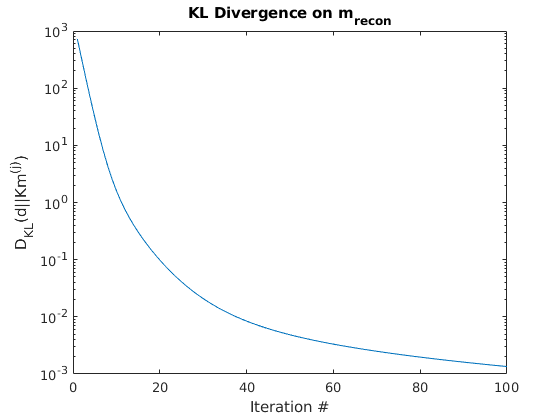

% plot KL Divergence and norm error
figure;
semilogy(1:100,KL_divergence); title('KL Divergence on m_{recon}');
ylabel('D_{KL}(d||Km^{(j)})'); xlabel('Iteration #');

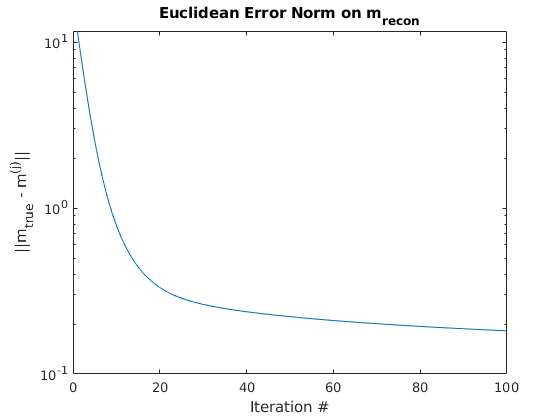

figure;
semilogy(1:100,norm_error); title('Euclidean Error Norm on m_{recon}');
ylabel('||m_{true} - m^{(j)}||'); xlabel('Iteration #');

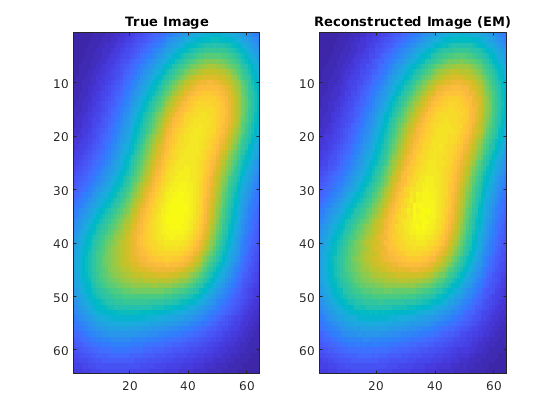

% plot true image vs. reconstructed
figure;
subplot(121);
imagesc(reshape(m_true, N, N)); title('True Image');
subplot(122);
imagesc(reshape(m_recon(:,101), N, N)); title('Reconstructed Image (EM)');

% B) Consider the noisy data case, i.e d is a realization of a Poisson
% distributed random vector.
% Design an appropriate stopping criterion for EM and reconstruct m
dn = poissrnd(K*m_true);

% initialize variables
iterations = 100;
mn_recon = ones(size(m_true,1),101);
KL_divergence_n = zeros(iterations,1);
norm_error_n = zeros(iterations,1);
residual_error_n = zeros(iterations,1);
for i=1:iterations
    fprintf('Iteration #: %d\n', i);
    mn_recon(:,i+1) = mn_recon(:,i).*SinvKT*(dn./(K*mn_recon(:,i)));
    KL_sum = dn.*log(dn./(K*mn_recon(:,i+1))); KL_sum_rn = KL_sum(~isnan(KL_sum)); % remove nans
    KL_divergence_n(i) = sum(KL_sum_rn,1);
    norm_error_n(i) = norm(m_true - mn_recon(:,i+1));
    residual_error_n(i) = norm(dn - K*mn_recon(:,i+1));
end

Iteration #: 1
Iteration #: 2
Iteration #: 3
Iteration #: 4
Iteration #: 5
Iteration #: 6
Iteration #: 7
Iteration #: 8
Iteration #: 9
Iteration #: 10
Iteration #: 11
Iteration #: 12
Iteration #: 13
Iteration #: 14
Iteration #: 15
Iteration #: 16
Iteration #: 17
Iteration #: 18
Iteration #: 19
Iteration #: 20
Iteration #: 21
Iteration #: 22
Iteration #: 23
Iteration #: 24
Iteration #: 25
Iteration #: 26
Iteration #: 27
Iteration #: 28
Iteration #: 29
Iteration #: 30
Iteration #: 31
Iteration #: 32
Iteration #: 33
Iteration #: 34
Iteration #: 35
Iteration #: 36
Iteration #: 37
Iteration #: 38
Iteration #: 39
Iteration #: 40
Iteration #: 41
Iteration #: 42
Iteration #: 43
Iteration #: 44
Iteration #: 45
Iteration #: 46
Iteration #: 47
Iteration #: 48
Iteration #: 49
Iteration #: 50
Iteration #: 51
Iteration #: 52
Iteration #: 53
Iteration #: 54
Iteration #: 55
Iteration #: 56
Iteration #: 57
Iteration #: 58
Iteration #: 59
Iteration #: 60
Iteration #: 61
Iteration #: 62
Iteration #: 63
I

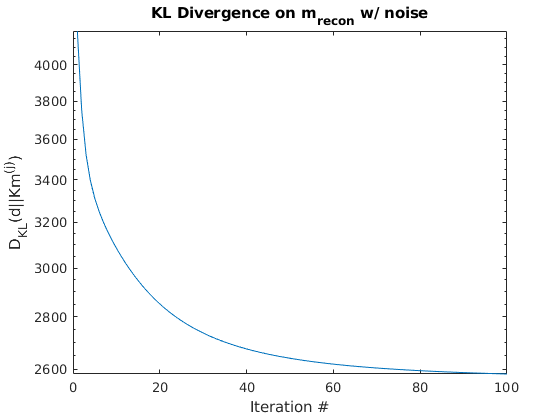

% plot KL Divergence and norm error
figure;
semilogy(1:100,KL_divergence_n); title('KL Divergence on m_{recon} w/ noise');
ylabel('D_{KL}(d||Km^{(j)})'); xlabel('Iteration #');

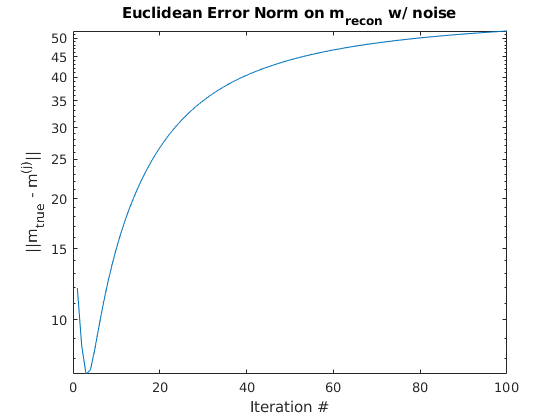

figure;
semilogy(1:100,norm_error_n); title('Euclidean Error Norm on m_{recon} w/ noise');
ylabel('||m_{true} - m^{(j)}||'); xlabel('Iteration #');

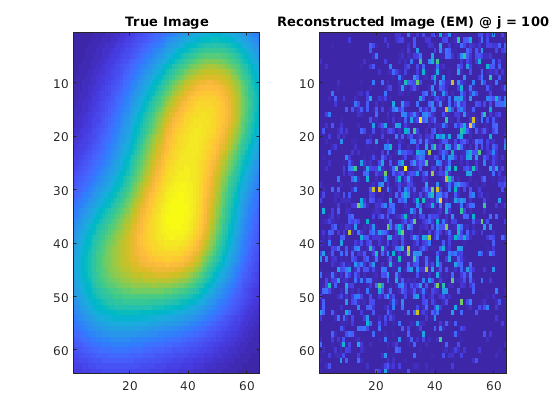

% plot true image vs. reconstructed (at last iteration)
figure;
subplot(121);
imagesc(reshape(m_true, N, N)); title('True Image');
subplot(122);
imagesc(reshape(mn_recon(:,101), N, N)); title('Reconstructed Image (EM) @ j = 100');

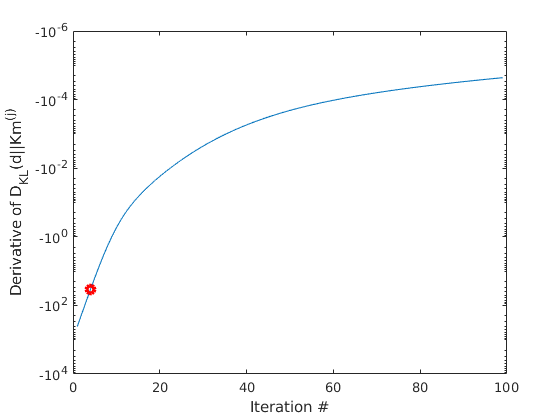

% look at the derivative of the KL divergence over iteration and 
% stop when it is at some threshold
dKL = KL_divergence(2:100)-KL_divergence(1:99);
threshold = 50; % set threshold for derivative
idx = find(abs(dKL) < threshold);

% plot things
figure; title('Derivative KL Divergence');
semilogy(1:99,dKL); hold on; semilogy(idx(1),dKL(idx(1)),'ro','Linewidth',3);
hold off;
xlabel('Iteration #'); ylabel('Derivative of D_{KL}(d||Km^{(j)}')

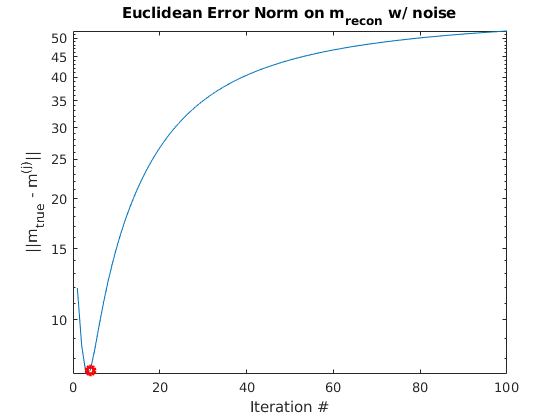

figure;
semilogy(1:100,norm_error_n); hold on; semilogy(idx(1),norm_error_n(idx(1)),'ro','Linewidth',3);
title('Euclidean Error Norm on m_{recon} w/ noise');
ylabel('||m_{true} - m^{(j)}||'); xlabel('Iteration #');
hold off;

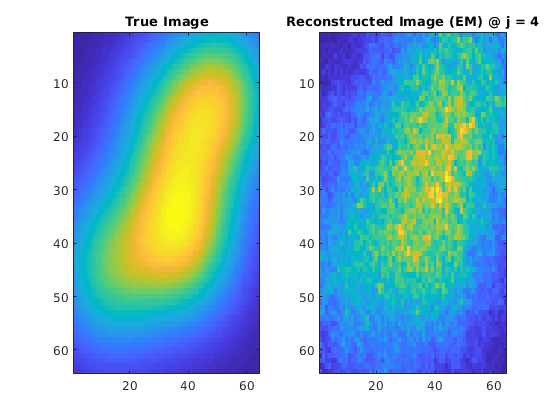

figure;
subplot(121);
imagesc(reshape(m_true, N, N)); title('True Image');
subplot(122);
imagesc(reshape(mn_recon(:,idx(1)), N, N)); title(['Reconstructed Image (EM) @ j = ' num2str(idx(1))]);